# Tema 5 - Integración Numèrica (III) 

### Matlab - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html)

### Matlab - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### Matlab - Integració adaptativa

%  quadgui(@(x)humps(x),0,1,1.0e-2)
integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

### Fórmules de Newton- Côtes

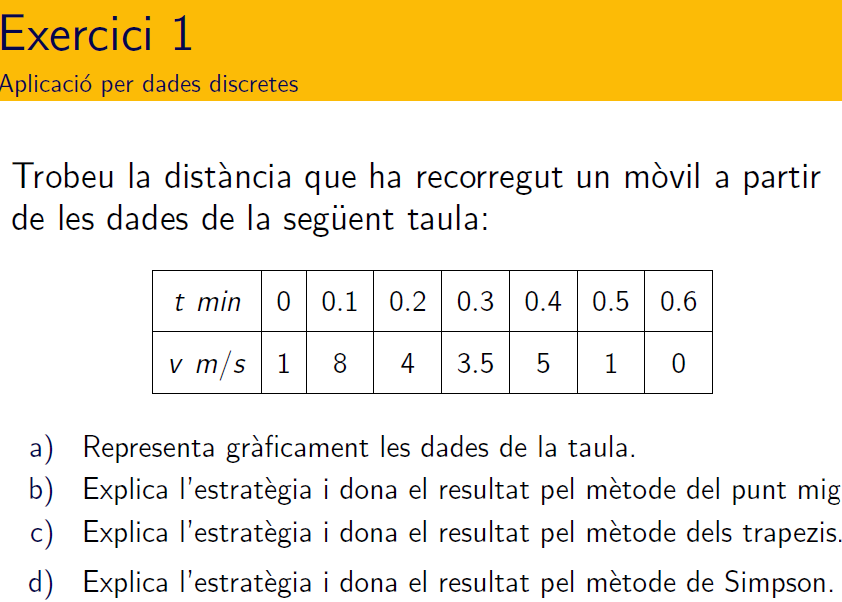

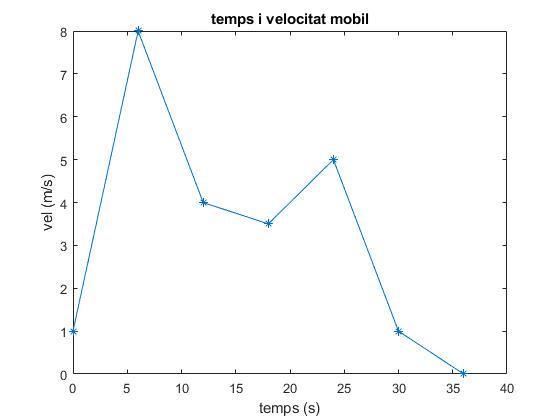

time = 0:0.1:0.6;
vel = [1 8 4 3.5 5 1 0];
x = time*60;
plot(x,vel,'-*'), title('temps i velocitat mobil')
xlabel('temps (s)'), ylabel('vel (m/s)')

- Distància calculada pel mètode dels trapezis  --> 132 metres

trapz(x,vel)

ans = 132

cumtrapz(x,vel)

ans =          0   27.0000   63.0000   85.5000  111.0000  129.0000  132.0000


- Distància calculada per la regla del punt mig  --> 150 metres

pm1 = (x(end)-x(1))*vel(4)

pm1 = 126

pm3 = (x(3)-x(1))*vel(2)+ (x(5)-x(3))*vel(4)+ (x(7)-x(5))*vel(6)

pm3 = 150

- Regla de Simpson ---> 138 metres

h = x(2)-x(1);
w=2*ones(size(vel));
w(2:2:end-1)=4; w([1,end])=1

w =      1     4     2     4     2     4     1


S=h/3*sum(w.*vel)

S = 138

S=h/3*(w*vel')

S = 138

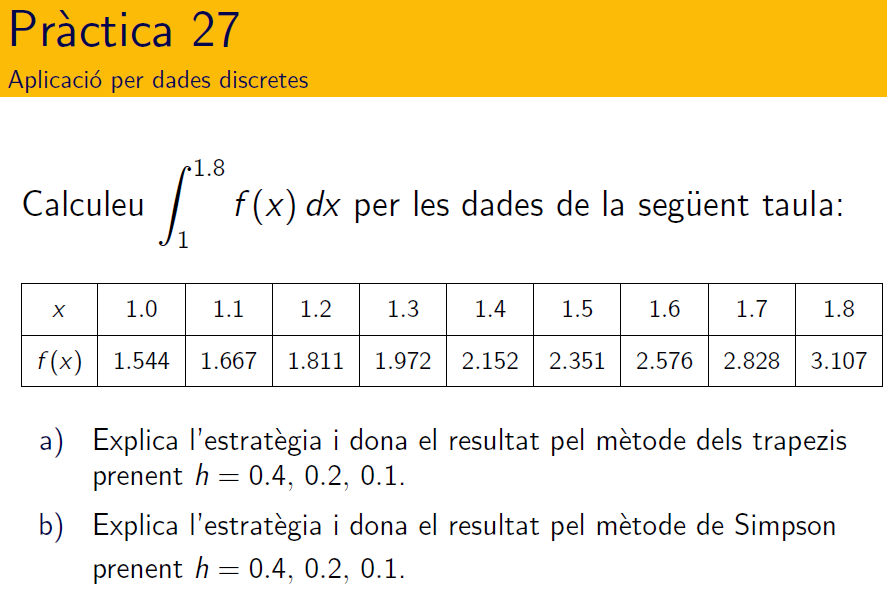

x = 1.0:0.1:1.8;

y = [1.544 1.667 1.811 1.972 2.152 2.351 2.576 2.828 3.107];

% plot(x,y,'-*'), title('dades')

- h=0.4, trapezis i simpson

h=0.4;
w = 2*ones(size(y));
w(2:2:end-1)=0; w([1,end])=1

w =      1     0     2     0     2     0     2     0     1


T = h/2*sum(w.*y)

T = 3.5458

h=0.4;
w = 4*ones(size(y));
w(2:2:end-1)=0; w([1,end])=1; w(5)=2

w =      1     0     4     0     2     0     4     0     1


S = h/6*sum(w.*y)

S = 1.7669

- h=0.1, trapezis i simpson

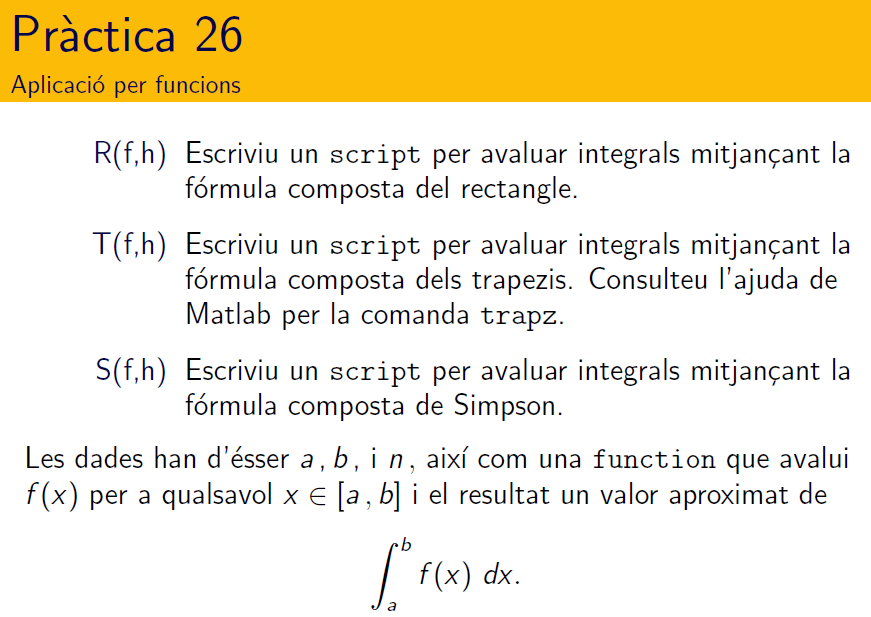

Verifiqueu els vostres codis amb el joc de proves de la pràctica 26. 

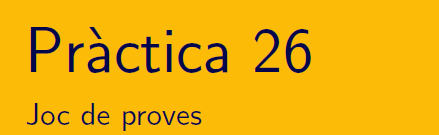


$${\rm a)\ } I=\displaystyle\int_{1}^{2} \ln(x)\,dx\,,\quad\quad
\int \ln(x)\, dx\, = x\ln(x)-x\,.$$


- valor analític

syms t
int(log(t),t)

$$ans = t\,\left(\log\left(t\right)-1\right)$$

ve = int(log(t),t,1,2), vec = double(ve)

$$ve = \log\left(4\right)-1$$

vec = 0.3863


a = 1; b=2; 
n = 50; 
x=linspace(a,b,n+1);
y=log(x);
T = trapz(x,y)

T = 0.3863

erabs = abs(T-vec)

erabs = 1.6666e-05

- Mètode de Romberg

a           =   1;
b           =   2;
I           =   Romberg(@(x)log(x),a,b);
fprintf('I\t=\t%0.15f\n',I);

I	=	0.386294361119891


RombergDisp(@(x)log(x),a,b,4);

0.346573590279973
0.376019349194069	0.385834602165434	
0.383699509409442	0.386259562814567	0.386287893524509	
0.385643909952095	0.386292043466313	0.386294208843096	0.386294309086248	
0.386131637744868	0.386294213675793	0.386294358356425	0.386294360729652	0.386294360932175	



$${\rm b)\ } I=\displaystyle\int_{0}^{\pi/4}{\cos}^2(x)\,dx\,,\quad
\int{\!\!\cos}^2(x)\, dx=\frac{\sin(2x)}{4}+\frac{x}{2}\,.$$


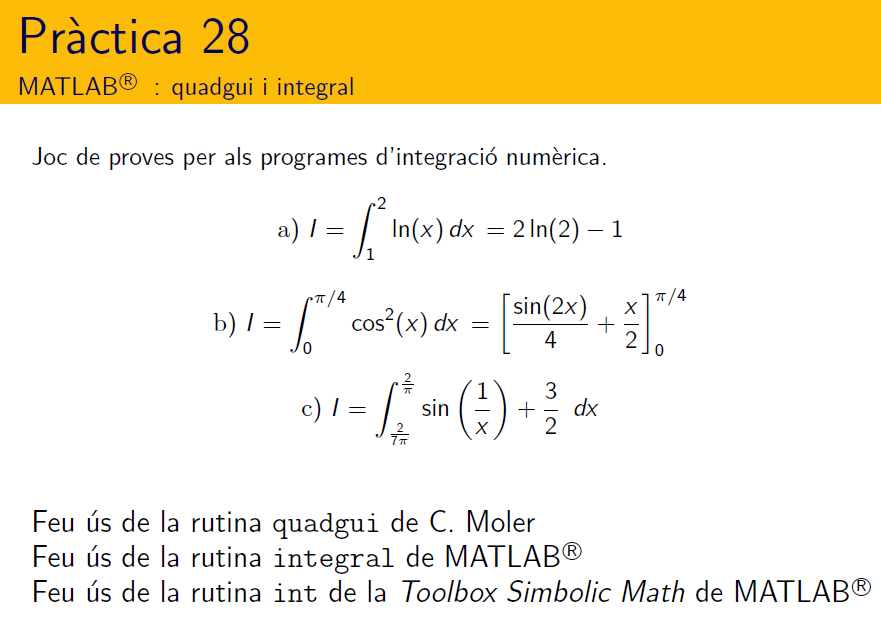

syms t
int(log(t),t)

$$ans = t\,\left(\log\left(t\right)-1\right)$$

ve = int(log(t),t,1,2), double(ve)

$$ve = \log\left(4\right)-1$$

ans = 0.3863

integral(@(t)log(t),1,2)

ans = 0.3863

integral(@(t)log(t),1,2,'RelTol',0,'AbsTol',1e-12)

ans = 0.3863

## Mètode de Romberg

JOC de PROVES

a) Calculeu el valor fent ús de punt mig

b) Calculeu el valor fent ús de trapezis

c) Apliqueu la taula d'extrapolació de romberg (podeu fer ús de [romberg.m](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) o un altre, verifiqueu el  vostre codi amb la taula següent)

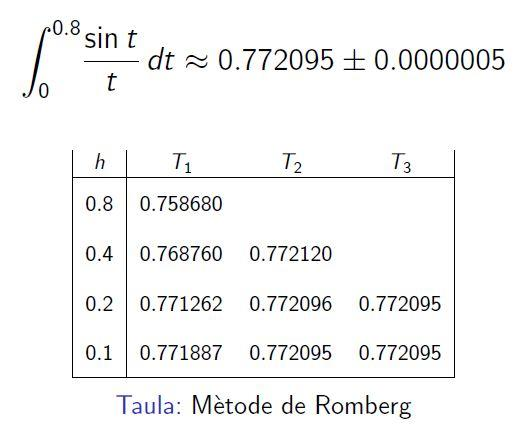

integral(@(x)log(x),1,2)

ans = 0.3863

quad(@(x)log(x),1,2)

ans = 0.3863

## Mètode de Montecarlo

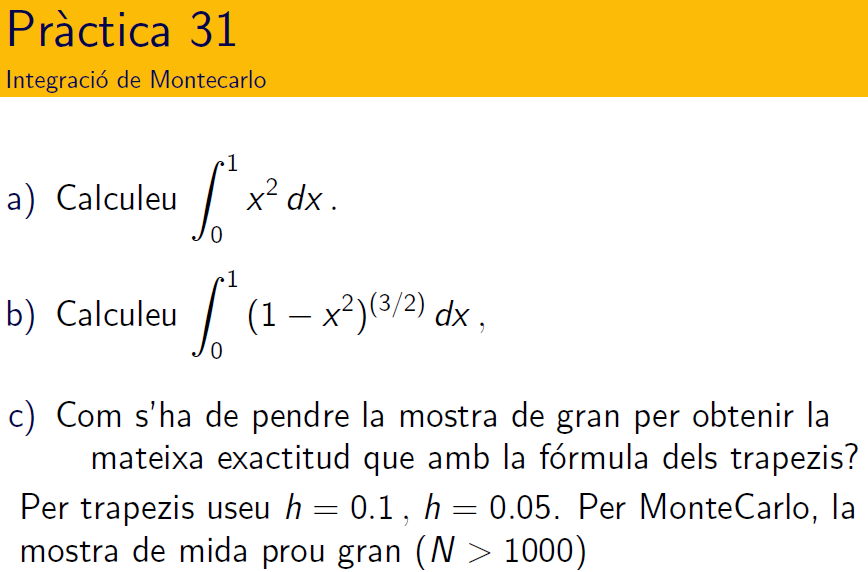

        
$$\quad a)\quad \int_0^1 x^2 dx = \frac{1}{3}$$
 

integral(@(x)x.^2,0,1)   % valor exacte

ans = 0.3333